# Lesson 7

Written by Brenda So and Cory Nezin, edited by Guy Bar Yosef

## Objective

After this class, you should be able to:

- Understand basic filtering techniques in MATLAB

- Be familiar with the MATLAB filter builder

- Implement basic edge-detection in MATLAB

- Understand how to switch between domains symbolically

# Filtering

Filtering is a very important topic in Signal Processing, allowing us to choose which frequencies of a signal we wish to keep and which to remove. In this lesson we will go over some of the techniques to build filters in MATLAB as well as show some examples of these filters in action.

We will begin with an example.

# Audio Example

Here we load in a standard MATLAB sound file, 'handel'.

load handel
audiowrite('handel.wav',y,Fs)
[y, Fs] = audioread('handel.wav');
sound(y, Fs);
T = 1/Fs;
t = 0:T:(length(y)-1)*T;

Now we add a high-frequency (2500Hz) interference to the signal. While contrived in this example, noisy data is a common hurdle EEs have to overcome.

noise = 0.2*sin(2.*pi.*t.*2500).';
y = noise + y;
sound(y, Fs); 

Let's visualize the signal spectrum using a Fourier Transform.

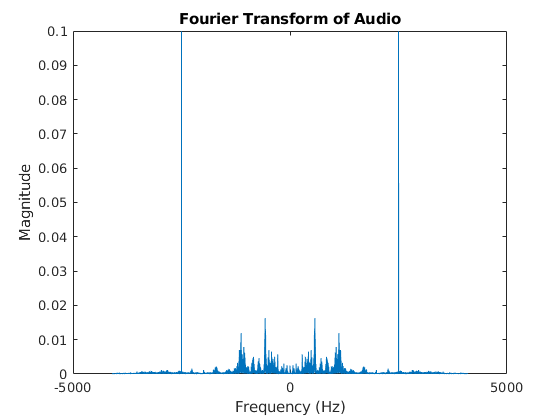

N= 2^15;
S = fft(y,N);
S = fftshift(abs(S))/N;
x_freq_dom = Fs.*(-N/2:N/2-1)/N;

figure
plot(x_freq_dom,S)
title('Fourier Transform of Audio')
xlabel('Frequency (Hz)')
ylabel('Magnitude')

Using the fourier transform we were able to reveal the frequencies of the noise! Now that we have identified which frequency the noise is at, let's filter it out.

# Filters Overview

For all filters, there are at least one passband and stopband. These refer to frequency ranges which will get through the filter and will get blocked by the filter, respectively.

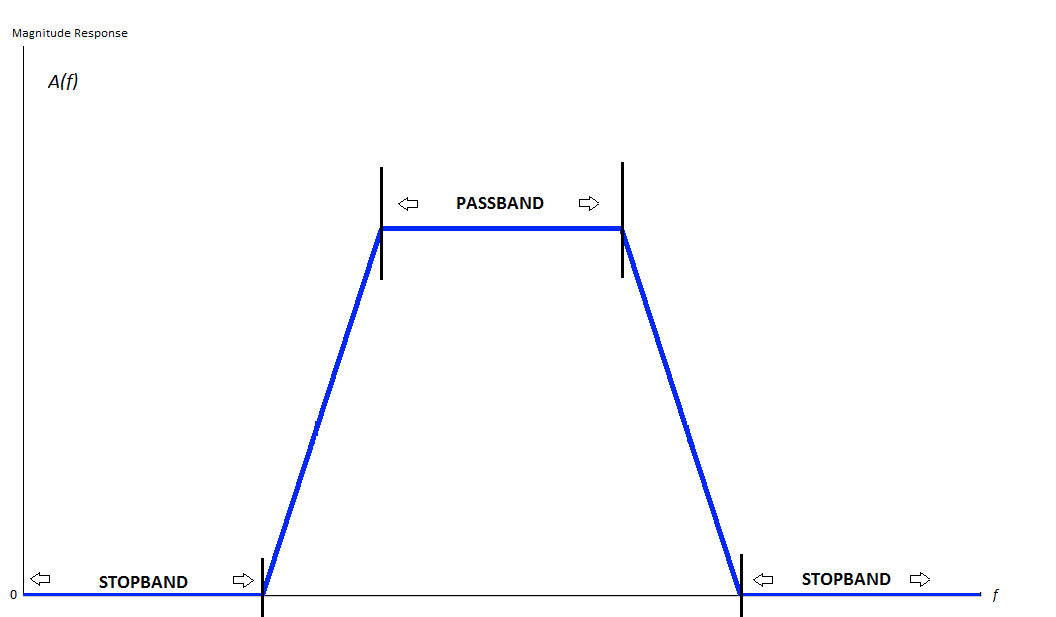

## There are 4 main types of filters:

- Lowpass - Lets pass low frequencies through

- Highpass - Lets pass high frequencies through

- Bandpass - Lets pass only a specific band of frequencies

- Bandstop - Stops a specific band of frequencies from going through

## There are primarily 4 implementations of filters

- Butterworth - maxflat passband, monotonic passband & stopband

- Chebychev I - equiripple passband, monotonic stopband

- Chevychev II - monotonic passband, equiripple stopband

- Elliptic - minimum order, equiripple passband & stopband

There are several ways to create filters: 

# Filter Design (GUI)

The following is a MATLAB application that allows you to easily design any type of filter. Afterward if you want you could export it into your workspace.

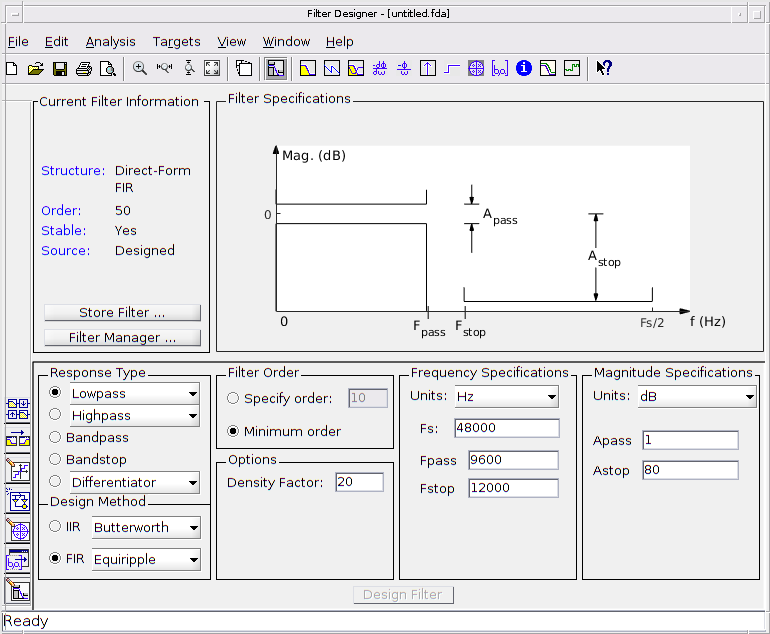

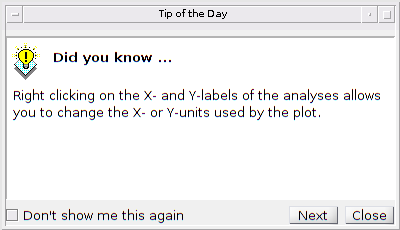

filterDesigner;

Another way you can create a filter is using MATLAB's digital signal processing toolbox:

Hd = getFilter % from file getFilter.m

Hd =   dsp.BiquadFilter with properties:

                   Structure: 'Direct form II'
             SOSMatrixSource: 'Property'
                   SOSMatrix: [3×6 double]
                 ScaleValues: [4×1 double]
           InitialConditions: 0
    OptimizeUnityScaleValues: true

  Show all properties


finalsound = step(Hd,y);
sound(finalsound,Fs);

Finally, one could also design filters using some useful MATLAB functions:

# Filter Design (Code)

Generate a butterworth filter with:

-  Fs = 44100 Hz

- Attenuation Pass = 1 dB

- Attenuation Stop = 80 dB

- Fpass = 1000 Hz

- Fstop = 10000 Hz

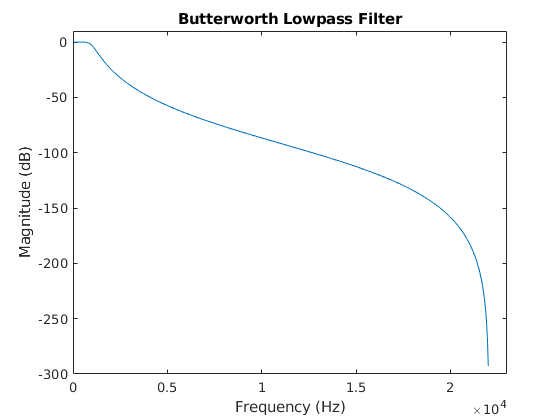

Fs = 44100;
Apass = 1;
Astop = 80;
Fpass = 1e3;
Fstop = 1e4;
wpass = 2*Fpass/Fs; % normalized to nyquist freq.
wstop = 2*Fstop/Fs; % normalized to nyquist freq.

% create the filter
n = buttord([wpass],[wstop],Apass,Astop);
[b,a] = butter(n,[wpass]);

% find the filter's frequency response
[Hight,Width] = freqz(b,a);

% plot the filter's Magnitude Response
lp_img = Width.*Fs/2/pi;
figure;
plot(lp_img, 20*log10(abs(Hight)));
title('Butterworth Lowpass Filter');
xlabel('Frequency (Hz)'), ylabel('Magnitude (dB)');
axis([0, 2.3e4, -300, 10])

Let's look at another example:

# Image Example of using a Low Pass Filter

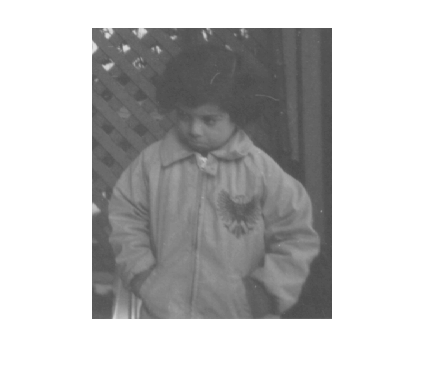

  Image with properties:

           CData: [291×240 double]
    CDataMapping: 'scaled'

  Use get to show all properties



% lets load in the image
x = imread('pout.tif');
x = double(x)/255; % not changing the image, just the underlying pixel datatype
figure
disp(imshow(x))

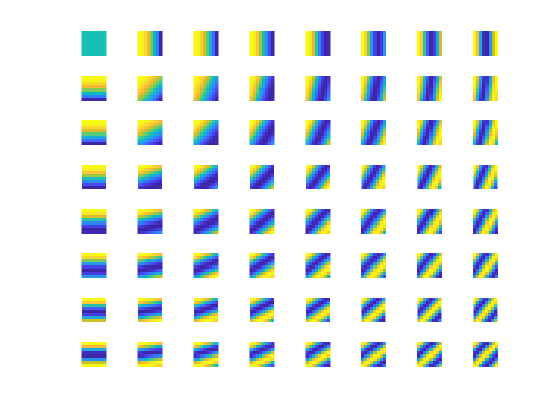

figure
[n,m] = ndgrid(0:7,0:7);
subplot_number = 1;
for nn = 0:7
    for mm = 0:7
        I = exp(1j*(n*nn+m*mm)/8);
        
        subplot(8,8,subplot_number)
        imagesc(real(I)); % each is an 8x8 image
        axis square
        axis off
        
        subplot_number = subplot_number + 1;
    end
end

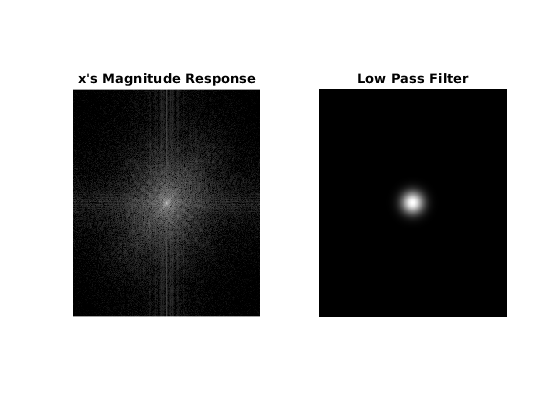

% take the fourier transform of x to bring to frequency domain
x_freq_dom = (fftshift(fft2(ifftshift(x))));
[Hight,Width] = size(x_freq_dom);

% a lowpass filter with dimentions of x_freq_dom
[h,w] = ndgrid( (1:Hight)-Hight/2, (1:Width)-Width/2 );
low_pass_filt = exp((-h.^2-w.^2)/200); 

figure
subplot(121)
imshow(log(abs(x_freq_dom))/max(log(abs(x_freq_dom(:)))))
title('x''s Magnitude Response')

subplot(122)
imshow(low_pass_filt)
title('Low Pass Filter')

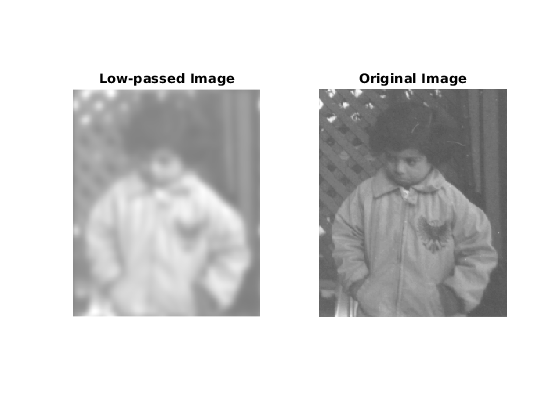

% convolv in time, multiply in frequency
lp_img_freq_dom = low_pass_filt.*x_freq_dom;

% inverse fourier transform back to 'time domain'
lp_img = real(fftshift(ifft2(ifftshift(lp_img_freq_dom))));

figure
subplot(121)
fnorm = abs(lp_img)/max(abs(lp_img(:)));
imshow(fnorm)
title('Low-passed Image')

subplot(122)
xnorm = abs(double(x))/max(double(x(:)));
imshow(xnorm)
title('Original Image')

So puting an image through a low-pass filter has the effect of blurring the image. This can be seen as a smoothing of the pixels by removing sharp changes in pixel values and only showing long-term changes. 

## Basic Edge Detection

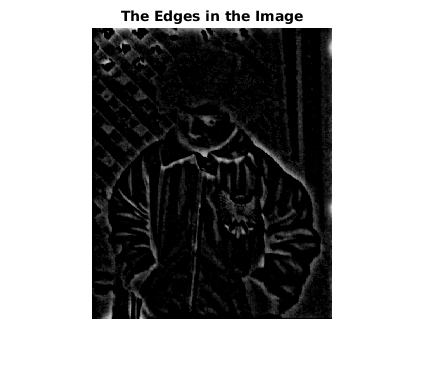

% the difference between the two filters are the sharp edges
sharp_image = lp_img - x; 
sharp_image_norm = sharp_image / max(sharp_image(:));

figure
imshow(sharp_image_norm)
title('The Edges in the Image')

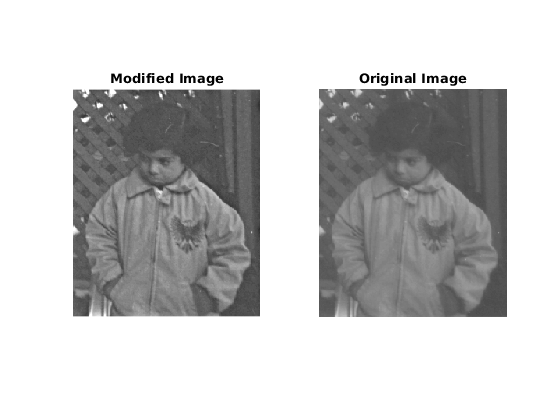

% Lets find a middle ground between the above and the original x
modified_img = x - 0.5*lp_img;
modified_img = 2*modified_img;

figure
subplot(121)
imshow(modified_img)
title('Modified Image')

subplot(122)
imshow(x)
title('Original Image')

And now for something completely different... 

# Laplace Transform in the Symbolic Toolbox

Take the transfer function

 
$$H(s) = \frac{-4s+8}{s^2+6s+8}$$


% finds the residues, poles, and constant of transfer function
[r,p,k] = residue([-4, 8],[1, 6, 8])

r =    -12
     8


p =     -4
    -2



k =

     []



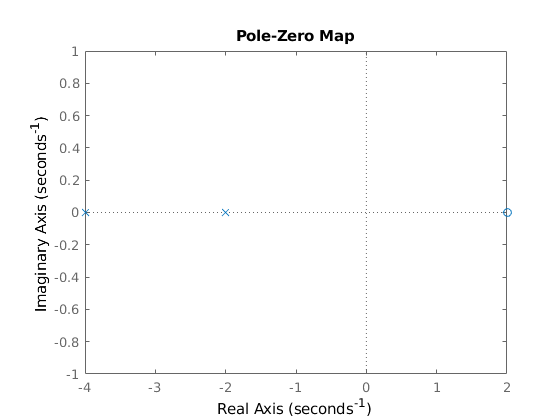

figure
pzmap([-4, 8],[1, 6, 8])

syms t a
lp_img = exp(-a*t);
laplace(lp_img)

$$ans = \frac{1}{a+s}$$

syms s
ilaplace(-4*s+8/(s^2+6*s+8))

$$ans = 4\,{\mathrm{e}}^{-2\,t}-4\,{\mathrm{e}}^{-4\,t}-4\,\delta^{\prime }(t)$$